# OFDM Radar 2D Correlation

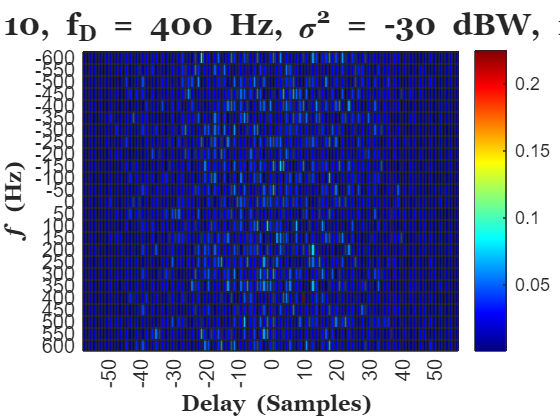

%% Computing and plotting the Ambiguity function for the OFDM waveform:

IEEEstandard = "802.11a";

% Let us define the OFDM system parameters based on the IEEE 802.11 standard
% in use:
switch (IEEEstandard)
    case "802.11a"
        subcarrierSpacing = 312.5e3; % subcarrier spacing for 802.11a
        Tu = 1/subcarrierSpacing; % the "useful" symbol period
        G = 1/8; % the guard interval fraction
        Tg = G*Tu; % the guard interval time
        To = Tu + Tg; % the OFDM symbol duration (period)
        fC = 5.5e9; % 802.11a uses the 5 GHz band
        N = 52; % 48 for data, and 4 pilot tones
        numPilotTones = 4; % no. pilot tones used 
    case "802.11g"
        subcarrierSpacing = 312.5e3; % subcarrier spacing for 802.11g
        Tu = 1/subcarrierSpacing; % the "useful" symbol period
        G = 1/8; % the guard interval fraction
        Tg = G*Tu; % the guard interval time
        To = Tu + Tg; % the OFDM symbol duration (period)
        fC = 2.4e9; % 802.11a uses the 2.4 GHz band
        N = 52; % 48 for data, and 4 pilot tones
        numPilotTones = 4; % no. pilot tones used
    case "802.11p"
        subcarrierSpacing = 78.125e3; % subcarrier spacing for 802.11g
        Tu = 1/subcarrierSpacing; % the "useful" symbol period
        G = 1/8; % the guard interval fraction
        Tg = G*Tu; % the guard interval time
        To = Tu + Tg; % the OFDM symbol duration (period)
        fC = 5.9e9; % 802.11a uses the 2.4 GHz band
        N = 52; % 48 for data, and 4 pilot tones
        numPilotTones = 4; % no. pilot tones used
end

M = 14; % no. of symbols in an OFDM frame
modOrder = 16; % order of modulation being used
modType = "QAM"; % type of modulation

switch(modType)
    case "QAM"
        signalSet = qammod((0:modOrder-1), modOrder, 'UnitAveragePower', true); % Generate the signal set for the relevant QAM scheme (16, 32, 64 etc.)     
    case "QPSK"
        signalSet = pskmod((0:modOrder-1), modOrder);
    otherwise
        disp("Check the status of 'modulationType' above.")
        return % Exit the program early
end

Ftx = zeros(N/2, M); % Half of the empty transmit frame

for row = 2:N/2 % We start at row 2, as row 1 is empty for the DC subcarrier...
    Ftx(row, :) = randsample(signalSet, M, true);
end

% The full transmit frame. Here we are imposing Hermitian symmetry, so that
% the output from the IFFT block is real-valued...
Ftx = [Ftx; zeros(1, M); conj(flip(Ftx(2:end, :), 1))];

% Add the cyclic prefix (CP):
cpLen = floor(G*N); % The cyclic prefix (CP) length
Ftx = [Ftx(end-cpLen+1:end, :); Ftx]; % Adding the cyclic prefix to each symbol

% Form the transmit sequence:
s = Ftx(:); % The transmit sequence s...

% Model the received sequence (r):
a = 9e-3; % How much the signal is attenuated by the target
L = N+cpLen; % The paper uses the extended block length (K + cyclic prefix length)
fD = 400; % The doppler shift caused by the target
delay = 10; % The delay of the received signal (r) in units of samples
p = 0:L*M-1; % The p vector, as discussed in the paper

% Computing the values in the received signal r:
noisedBW = -30;
Z = wgn(length(s), 1, noisedBW, 'complex'); % Complex Gaussian White noise vector...
dopplerShift = exp(1i*2*pi*fD*p/L).';
r = [zeros(delay, 1); a*dopplerShift.*s + Z]; % The received signal; adding the delay...

p = 0:L-1; % Redefining the vector p for the next part of the calculation
nu = -600:50:600; % The Greek letter "Nu", which looks like a 'v', is standing for the frequency of the E.M. wave...

% The very big matrix below will store all the
% Xm matrices:
Xm_storage = zeros(M*length(nu), 2*L-1);

% The matrix below is the result of multiplying the p vector
% by each value in the nu vector, and storing the results in
% the rows of this "p_nu_matrix" matrix. This is simply being
% used to do the computations compactly.
p_nu_matrix = p.*nu';

% The term below appears at the end of equation 6 in the paper:
negDopplerShift = exp(-1i*2*pi*p_nu_matrix/L);

% Preallocating enough memory for this variable which will be used inside
% the for loop below. The number of rows equals the number of subcarriers
% (K) plus the delay (in units of samples):
r_dash = zeros(L, length(nu));

% This for loop works out Xm, as stated in the paper:
for block = 1:M
    n = block - 1; % This is an index variable used for forming rm and sm
    
    % sm stands for the part of s which forms OFDM symbol or
    % "block" m. rm stands for the part of r which is considered as the
    % block or symbol m at the receiver:
    sm = s(1+L*n: L*n + L); % The signal sm
    rm = r(1+L*n: L*n + L); % The signal rm
    r_dash = rm.*negDopplerShift.';
    
    % Now to calculate the correlation:
    Xm = zeros(length(nu), 2*L-1);
    
    % Computing Xm by using the xcorr() function
    for j = 1:length(nu)
        Xm(j, :) = xcorr(r_dash(:, j), sm);
    end
    
    Xm = (1/sqrt(N))*Xm; % Scaling, as shown in equation 6
    % Now we load this matrix for Xm into the storage matrix so it can be
    % further processed later on...
    Xm_storage(length(nu)*block-length(nu)+1: length(nu)*block, :) = Xm;
end

% By this stage we have Xm calculated for each value of m, where m is the
% index or block number - going from 0 to (M-1). Now we can work out
% equation 5:

negDopplerShift_m = exp(-1i*2*pi*nu'.*(0:M-1)); % Term used in equation 5

% This is a matrix to store the overall result of the
% ambiguity function. The values in this matrix will
% be computed using the contents of the Xm matrix.
Xm_dash = zeros(M*length(nu), 2*L-1);

for block = 1:M
    startRowIndex = length(nu)*block - length(nu) + 1;
    endRowIndex = length(nu)*block;
    % The term below (Xm_dash) is the equal to the product of the two terms
    % to the right of the "sum" symbol in equation 5:
    Xm_dash(startRowIndex: endRowIndex, :) = Xm_storage(startRowIndex: endRowIndex, :).*negDopplerShift_m(:, block);
end

% This matrix below will store the final result of the ambiguity function
% computation:
X = zeros(length(nu), 2*L-1);

% Now to implement equation 5:
for block = 1:M
    startRowIndex = length(nu)*block - length(nu) + 1;
    endRowIndex = length(nu)*block;
    X(1:length(nu), :) = X(1:length(nu), :) + Xm_dash(startRowIndex: endRowIndex, :);
end

X = (1/(sqrt(M)))*X; % Scaling, as shown in the paper in equation 5

delayVec = -L+1:L-1; % A vector of delays or lags (in units of samples)
delayLabels = string(delayVec);
delayLabels(~(mod(delayVec, 10) == 0)) = ""; % If value in vector is NOT divisble by 10, leave blank
freqLabels = string(nu);
freqLabels(~(mod(nu, 10) == 0)) = ""; % If value in vector is NOT divisble by 10, leave blank

h = heatmap(delayVec, nu, abs(X), 'Colormap', jet(300));
title("\fontsize{14}\fontname{Georgia}2D-Correlation Receiver ("+IEEEstandard + ", \tau = " + delay + ", f_{D} = " + fD + " Hz, \sigma^{2} = " + noisedBW + " dBW, " + modOrder + "-" + modType + ", N = " + N + ", M = " + M + ", G = " + G + ")");
xlabel('\fontname{Georgia}\bf Delay (Samples)');
ylabel('\fontname{Georgia}\bf\itf\rm\bf (Hz)');
h.XDisplayLabels = delayLabels;
h.YDisplayLabels = freqLabels;